# **MEC4127F: Introduction to Robotics**

# Chapter 4: Pose estimation

## 4.1 Introduction

...

Inertial navigation systems

## 4.2 Inertial measurement units

### 4.2.1 Gyroscopes

Any sensor that measures the rate of change of orientation is known as a gyroscope.

#### 4.2.1.1 Measurement equation

The generalised measurement equation of a gyroscope is given by


$${^B{\bf \omega}^\#}={^B{\bf \omega}}+{\bf b}_\omega+{\bf n}_\omega,$$


where ${^B{\bf \omega}}$ is the true angular velocity experienced by the sensor, ${^B{\bf \omega}^\#}$ is the measured signal, with the superscript $\#$ indicating a measured quantity, ${{\bf b}_\omega}$ is an unknown and time-varying bias term, and ${{\bf n}_\omega}$ is nondeterministic measurement noise, which is often treated as white noise.

#### 4.2.1.2 Bias compensation

The unknown bias term of ${{\bf b}_\omega}$ needs to be accounted for when estimating angular velocity. Angular velocity bias is temperature dependant and has an approxiately linear relationship with incremental changes in temperature. For this reason, most MEMS IMUs also include temperature sensing modules to actively account for this. The bias term can be approximately inferred from IMU temperature based on


$${\overline{\bf b}_\omega} =  {{\bf b}_\omega}(0)+{\bf C} \Delta T^\#,$$


where ${\overline{\bf b}_\omega} $ is the estimated bias term, with the overbar of $\overline$ indicating the parameter is an estimate, ${{\bf b}_\omega}(0)$ is the initial bias term at time $t=0$, ${\bf C}$ is a diagonal matrix of gradient coefficients, and $\Delta T^\#$ is the measured differential temperature on the IMU.

If the IMU is constrained such that angular velocity is not experienced, then the measurement equation becomes


$$\begin{array}{ll}
{^B{\bf \omega}^\#}
&={\bf b}_\omega+{\bf n}_\omega,\\
&\approx {{\bf b}_\omega}(0)+{\bf C} \Delta T^\#+{\bf n}_\omega.
\end{array}$$


In this configuration, as the gyroscope experiences an increase of temperate, a corresponding straight line response will be seen on each channel of the gyroscope, with the respective y-intercepts corresponding to ${{\bf b}_\omega}(0)$, and the gradients corresponding to the diagonal elements of $\bf C$. One can therefore de-bias the gyroscope reading using ${{\bf b}_\omega^\hat}$ if the sensor has been calibrated, which yields an estimate for the angular velocity, namely


$$\begin{array}{ll}
{^B\overline{\bf \omega}}
&={^B{\bf \omega}^\#}-{\overline{\bf b}_\omega},\\
&={^B{\bf \omega}}+\left({\bf b}_\omega-{{\overline{\bf b}_\omega}}\right)+{\bf n}_\omega, \\
&\approx{^B{\bf \omega}}+{\bf n}_\omega.
\end{array}$$


#### Example: Calibrating a gyroscope

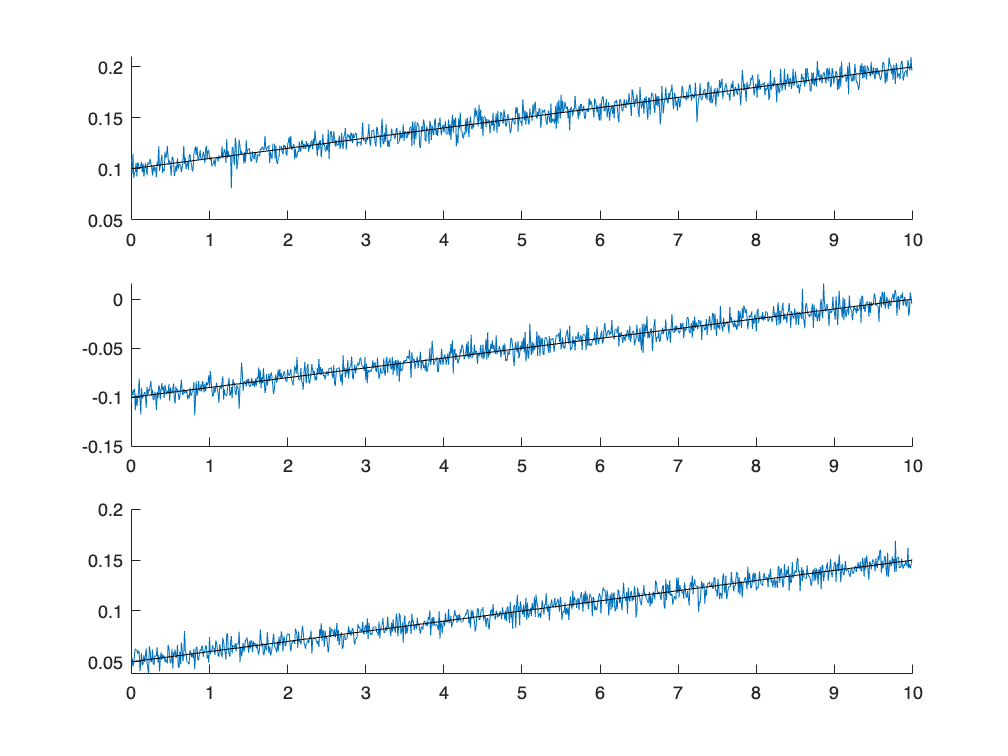

IMU = imuSensor;
IMU.Gyroscope.NoiseDensity = 1e-3;
IMU.Gyroscope.ConstantBias = [0.1 -0.1 0.05];
IMU.Gyroscope.TemperatureBias = 1e-3*ones(1,3);
IMU.Temperature = 25;

dT = 0.01;
numSamples = 1000;
t = (0:numSamples-1)*dT;

omega = zeros(1,3);
omege_meas = zeros(numSamples,3);
temp = zeros(numSamples,1);

for k=1:numSamples
    [~,omega_meas(k,:)] = IMU(zeros(1,3),omega);
    temp(k) = IMU.Temperature;
    IMU.Temperature = IMU.Temperature+0.1;
   

end

b = IMU.Gyroscope.ConstantBias + (temp-25) * IMU.Gyroscope.TemperatureBias(1);

figure,
subplot(3,1,1), hold on
plot(t,omega_meas(:,1))
plot(t,b(:,1),'k')
subplot(3,1,2),hold on
plot(t,omega_meas(:,2))
plot(t,b(:,2),'k')
subplot(3,1,3),hold on
plot(t,omega_meas(:,3))
plot(t,b(:,3),'k')

Using $\begin{array}{ll}
{^B\overline{\bf \omega}}
&={^B{\bf \omega}^\#}-{\overline{\bf b}_\omega}
\end{array}$, we can plot the resulting estimated angular velocity, which we know should be equal to zero.

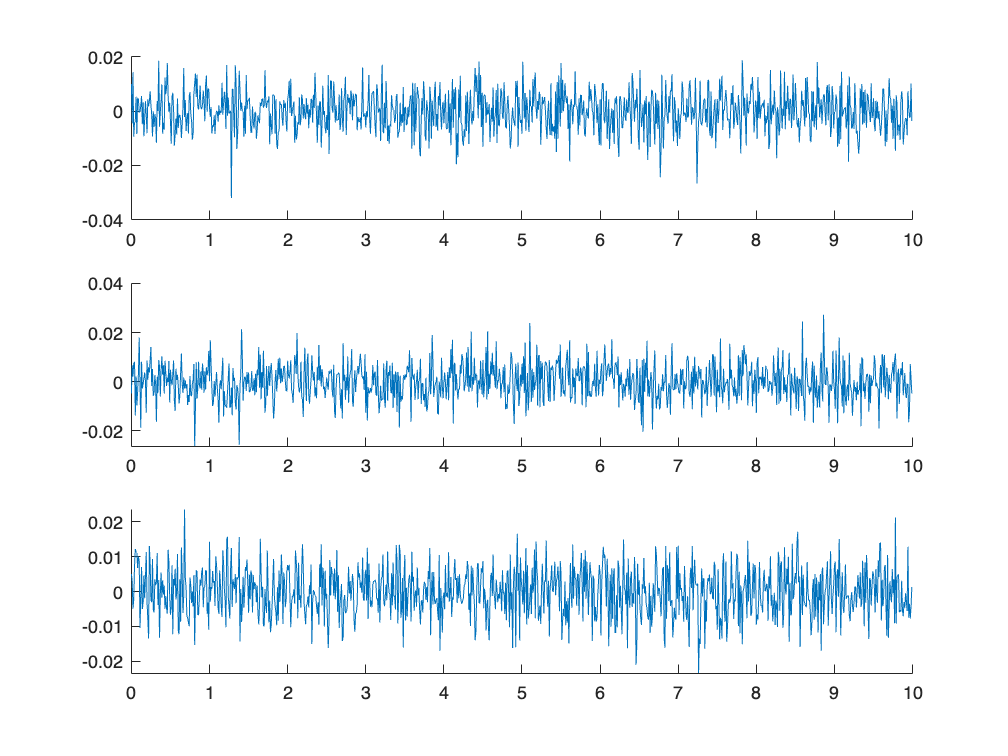

figure,
subplot(3,1,1), hold on
plot(t,omega_meas(:,1)-b(:,1))
subplot(3,1,2),hold on
plot(t,omega_meas(:,2)-b(:,2))
subplot(3,1,3),hold on
plot(t,omega_meas(:,3)-b(:,3))

#### 4.2.1.3 Orientation estimation using rotation matrices

Recall from Chapter 3 that if the angular velocity is exactly known for a period of $\Delta t$ units of time, then the incremental exponential coordinates are given by


$${^B\Delta{\bf \theta}={^B{\bf \omega}}\Delta t.$$


The incremental axis-angle form was given by


$$\Delta \alpha=|{^B{\bf \omega}}|\Delta t,$$
           
$${^B\hat{\bf \omega}}=\frac{^B{\bf \omega}}{|{^B{\bf \omega}}|},$$


and the corresponding incremental rotation matrix was


$$\begin{array}{ll}
\Delta{\bf R}
&=\mathrm{e}^{\lfloor {^B{\Delta\bf \theta}} \rfloor},\\
&=\mathrm{e}^{\lfloor {^B{\bf \omega}}\Delta t \rfloor},\\
&={\bf I}+\sin\Delta\alpha\lfloor ^B\hat{\bf \omega} \rfloor +\left(1-\cos\Delta\alpha\right)\lfloor ^B\hat{\bf \omega} \rfloor^2,\\
&={\bf I}+\sin(|{^B{\bf \omega}}|\Delta t)\lfloor ^B\hat{\bf \omega} \rfloor +\left(1-\cos(|{^B{\bf \omega}}|\Delta t)\right)\lfloor ^B\hat{\bf \omega} \rfloor^2.
\end{array}
$$


Assuming that the angular velocity measurement has been sufficiently de-biased, one can similarly integrate ${^B\overline{\bf \omega}}$ to obtain an orientation *estimate*. Replacing ${^B{\bf\omega}}$ with ${^B\overline{\bf\omega}}$ for the above equations yields


$${^B\Delta\overline{\bf \theta}={^B\overline{\bf \omega}}\Delta t,$$
     
$$\Delta \overline\alpha=|{^B\overline{\bf \omega}}|\Delta t,$$
      
$${^B\overline\hat{\bf \omega}}=\frac{^B\overline{\bf \omega}}{|{^B\overline{\bf \omega}}|},$$


and 


$$\begin{array}{ll}
\Delta\overline{\bf R}
&=\mathrm{e}^{\lfloor {^B{\Delta\overline{\bf \theta}}} \rfloor},\\
&=\mathrm{e}^{\lfloor {^B\overline{\bf \omega}}\Delta t \rfloor},\\
&={\bf I}+\sin\Delta\overline\alpha\lfloor ^B\overline\hat{\bf \omega} \rfloor +\left(1-\cos\Delta\overline\alpha\right)\lfloor ^B\overline\hat{\bf \omega} \rfloor^2,\\
&={\bf I}+\sin(|{^B\overline{\bf \omega}}|\Delta t)\lfloor ^B\overline\hat{\bf \omega} \rfloor +\left(1-\cos(|{^B\overline{\bf \omega}}|\Delta t)\right)\lfloor ^B\overline\hat{\bf \omega} \rfloor^2.
\end{array}
$$


An estimated angular velocity experienced by a rigid body that moves it from frame $\{0\}$ to $\{1\}$ over a period of $\Delta t$ units is then described by


$${^W\overline{\bf R}_{\{1\}}}={^W\overline{\bf R}_{\{0\}}}{^{\{0\}}\overline{\bf R}_{\{1\}},$$
 

where $\Delta\overline{\bf R}={^{\{0\}}\overline{\bf R}_{\{1\}}
$ is the incremental orientation as a result of the body-frame angular velocity. 

In practice, angular velocity measurements will be obtained from a gyroscope at discrete intervals, as opposed to being a continuous signal. If we make the assumption that the angular velocity is constant during each sampling instance of length $\Delta t$, then we define our incremental rotation at sample time $k$ as 


$$\begin{array}{ll}
\Delta\overline{\bf R}_k
&={^{\{k-1\}}{\bf R}_{\{k\}},\\
&=\mathrm{e}^{\lfloor {^B\overline{\bf \omega}_k}\Delta t \rfloor},\\
&={\bf I}+\sin\Delta\overline\alpha_k\lfloor ^B\overline\hat{\bf \omega}_k \rfloor +\left(1-\cos\Delta\overline\alpha_k\right)\lfloor ^B\overline\hat{\bf \omega}_k \rfloor^2,\\
&={\bf I}+\sin(|{^B\overline{\bf \omega}_k}|\Delta t)\lfloor ^B\overline\hat{\bf \omega}_k \rfloor +\left(1-\cos(|{^B\overline{\bf \omega}_k}|\Delta t)\right)\lfloor ^B\overline\hat{\bf \omega}_k \rfloor^2.
\end{array}
$$


The estimated orientation at sample instance $k$ follows as


$$\begin{array}{ll}
{^W\overline{\bf R}_{\{k\}}}
&={^W\overline{\bf R}_{\{0\}}}{^{\{0\}}\overline{\bf R}_{\{1\}} \dots {^{\{k-1\}}\overline{\bf R}_{\{k\}},\\
&={^{W}\overline{\bf R}_{\{k-1\}} {^{\{k-1\}}\overline{\bf R}_{\{k\}},\\
\end{array}$$
 

where each rotation matrix estimate is obtained from a particular sampling instance, after integrating the angular velocity and applying the exponential coordinate mapping. 

The angular velocity estimate ${^B\overline{\bf \omega}}$ is notably imperfect, as a result of sensor resolution, noise term ${\bf n}_\omega$, as well as the potential biasing as a result of ${{\overline{\bf b}_\omega}}\neq{\bf b}_\omega$. Additionally, the assumption that the estimated angular velocity is constant for the full duration of the sampling period will also result in an imperfect estimate of the incremental exponential coordinates, based on ${^B\Delta\overline{\bf \theta}={^B\overline{\bf \omega}}\Delta t$. For this reason, the orientation estimate using the approach outline above will ultimately experience drift (or random walk) that cannot be compensated for. The result is that the orientation estimate will become poorer over time, as the errors from the imperfect angular velocity estimate and sampling assumptions accumulate. This problem can be solved using sensor fusion, which is introduced in Section 4.3.

#### 4.2.1.4 Orientation estimation using quaternions

As shown in Chapter 3, The quaternion is an alternative approach to determining orientation from angular velocity information. Given an angular velocity estimate of ${^B\overline{\bf \omega}}_k$ at sample instance $k$, the angle-axis representation of the incremental rotation can be determined by


$$\Delta \overline\alpha_k=|{^B\overline{\bf \omega}_k}|\Delta t,$$
      
$${^B\overline\hat{\bf \omega}_k}=\frac{^B\overline{\bf \omega}_k}{|{^B\overline{\bf \omega}_k}|},$$


which is equivalent to the axis-angle representation of the incremental exponential coordinates in the previous subsection. The incremental quaternion at sample instance $k$ follows as


$$\begin{array}{cc}\Delta\overline{\mathbf q}_k =
{^{\{k-1\}}\overline{\bf q}_{\{k\}}
= \left[\begin{array}{cc}    \cos{\frac{\Delta\overline\alpha_k}{2}} \\ \sin{\frac{\Delta\overline\alpha_k}{2}} {^B\overline\hat{\mathbf \omega}_k}     \\ \end{array}\right],\end{array}$$


with the absolute estimated quaternion given by


$$\begin{array}{ll}
{^W\overline{\bf q}_{\{k\}}}
&={^W\overline{\bf q}_{\{0\}}}\otimes{^{\{0\}}\overline{\bf q}_{\{1\}}\otimes \dots \otimes{^{\{k-1\}}\overline{\bf q}_{\{k\}}, \\
&={^W\overline{\bf q}_{\{k-1\}}} \otimes{^{\{k-1\}}\overline{\bf q}_{\{k\}}.
\end{array}$$
 

As with the rotation matrix approach, estimating the quaternion orientation using only estimated (and imperfect) angular velocity information will result in orientation errors over time.

#### 4.2.1.5 Normalisation

The process of estimating orientation using rotation matrices or quaternions requires iterative multiplication of matrices or vectors. Given that the hardware (e.g microcontroller or computer) used to make these computations has finite precision, subsequent multiplication operations, followed by numerical truncation, will eventually result in rotation matrices not being orthogonal, or quaternions not being unitary (have unit length). To compensate for this, we can perform a normalisation step at regular intervals, such as after every few samples (the frequency would depend on the numerical precision of the hardware).

**Rotation matrices**

The basic concept is to enforce each column of the matrix to be orthogonal to the other columns, with unit magnitudes (to preserve the orthogonal property of a rotation matrix). This is done by first selecting one column of  


$${{\mathbf R}}=[{\mathbf c}_1  ~{\mathbf c}_2 ~ {\mathbf c}_3]$$


such as column three, ${\mathbf c}_3$, and assume that the direction is correct, namely


$$\begin{array}{cc}    {\mathbf c}^{'}_3={\mathbf c}_3.\\ \end{array}$$


The (updated) first column, ${\bf c}_1^{'}$, is then set to be orthogonal to the last two columns


$$\begin{array}{cc}    {\mathbf c}^{'}_1={\mathbf c}_2 \times {\mathbf c}^{'}_3.\\ \end{array}$$


Given that the last two columns may not have been orthogonal, we define the second column to be orthogonal to the first and third column


$$\begin{array}{cc}    {\mathbf c}^{'}_2={\mathbf c}^{'}_3 \times {\mathbf c}^{'}_1.\\ \end{array}$$


Finally, each column is individually normalised, in order to preserve unit length


$$\begin{array}{cc}    {\mathbf c}^{'}_i=\frac{ {\mathbf c}^{'}_i }{|{\mathbf c}^{'}_i|},  \forall i\in [1,3].\\ \end{array}$$


The resulting normalised rotation matrix follows as  


$${{\mathbf R}^{'}}=[{\mathbf c}^{'}_1 ~ {\mathbf c}^{'}_2 ~ {\mathbf c}^{'}_3],$$


which now adheres to the othogonality requirements of SO(3).

**Quaternions**

As with the rotation matrix update, we require normalisation of the quaternion in order to maintain the unitary structure. In the case of the quaternion, normalisation simply requires dividing all elements by the quaternion norm


$$\begin{array}{cc}{{\mathbf q}} = \frac{{{\mathbf q}}}{|{{\mathbf q}}|}, \end{array}$$


which is also computationally efficient.

#### Example

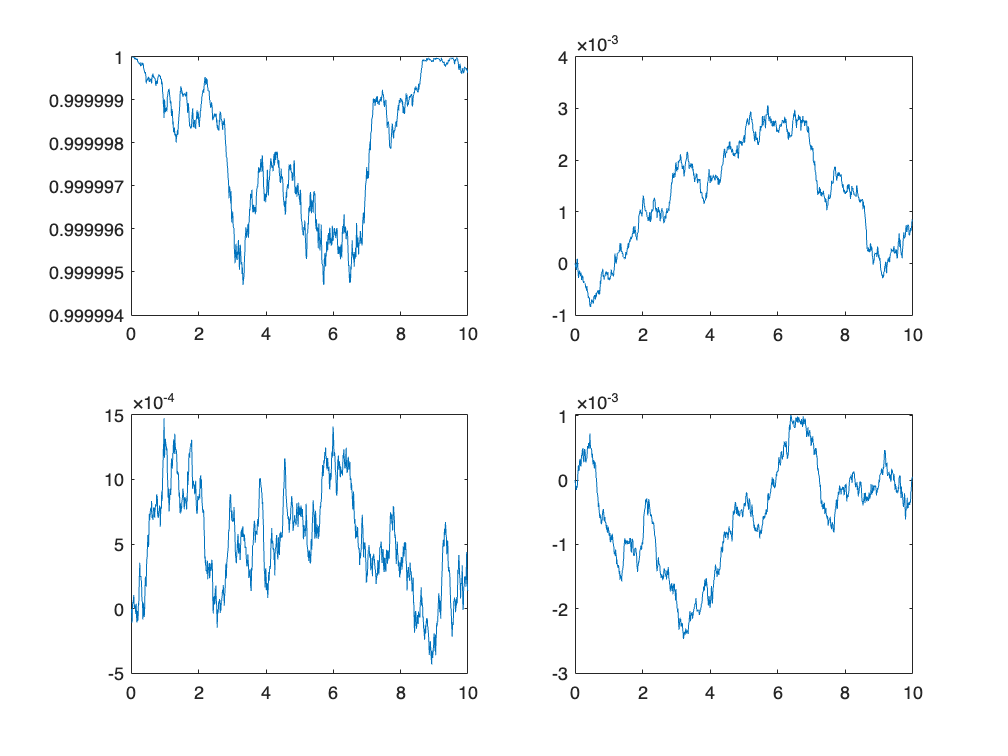

IMU = imuSensor;
IMU.Gyroscope.NoiseDensity = 1e-3;
% IMU.Gyroscope
dT = 0.01;
numSamples = 1000;
t = (0:numSamples-1)*dT;

omega = zeros(numSamples,3);
[~,omega_meas] = IMU(zeros(numSamples,3),omega);


q = zeros(numSamples,4);
q(1,1:4) = [1 0 0 0];

for k=1:numSamples-1
    dtheta = omega_meas(k,:)*dT;
    dalpha = norm(dtheta);
    v = dtheta/dalpha;
    dq = [cos(dalpha) sin(dalpha)*v];
    q(k+1,1:4) = quatmultiply(q(k,1:4),dq);
    q(k+1,1:4) = q(k+1,1:4)/norm( q(k+1,1:4) );
end
figure, hold on
subplot(2,2,1),plot(t,q(:,1))
subplot(2,2,2),plot(t,q(:,2))
subplot(2,2,3),plot(t,q(:,3))
subplot(2,2,4),plot(t,q(:,4))

### 4.2.2 Accelerometers

### 4.2.3 Magnetometers

## 4.3 Sensor fusion

### 4.3.1 TRIAD algorithm

### 4.3.2 Complementary filter

### Incremental rotations 

The time derivative of a rotation matrix or quaternion does not have obvious geometric meaning. Simply put,  $\dot{\mathbf R}$ or  $\dot{\mathbf q}$ shows how the respective elements change with time.

#### Rotation matrices 

Starting with the rotation matrix encoding, we can use a first-order approximation to describe the derivative 


$$\begin{array}{cc}{^W\dot{\mathbf R}_B} \approx \frac{{^W{\mathbf R}_B(t+\Delta t)}-{^W{\mathbf R}_B(t)}}{\Delta t},& \qquad (65)\\ \end{array}$$


where  ${^W\dot{\mathbf R}_B}\in \mathbb{R}^{3\times 3}$ is not, in general, an orthonormal matrix. Note that  $^W{\mathbf R}_B(t)$ encodes the orientation at time  $t$ , and  $^W{\mathbf R}_B(t+\Delta t)$ encodes the orientation at time  $t+\Delta t$ . We can use our understanding of sequential rotations to show how an incremental rotation matrix,  $\Delta{\mathbf R}$ , adjusts the orientation when moving from time  $t$ to  $t+\Delta t$ 


$$\begin{array}{cc}{^W{\mathbf R}_B(t+\Delta t)}={^W{\mathbf R}_B(t)} \Delta{\mathbf R}.& \qquad (66)\\ \end{array}$$


To help make sense of the rotation order, we write  ${^W{\mathbf R}_B(t)}$ as  ${^W{\mathbf R}_{B(t)}}$ . As  $\Delta{\mathbf R}$ is an incremental rotation that starts in frame  $\{B\}$ at time  $t$ (frame  $\{B(t)\}$ ), and rotates the body-frame to frame  $\{B(t+\Delta t)\}$ , we can rewrite \eqref{eq: R=RdR} as 


$$\begin{array}{cc}{^W{\mathbf R}_{B(t+\Delta t)}}={^W{\mathbf R}_{B(t)}} {^{B(t)}\Delta{\mathbf R}_{B(t+\Delta t)}},& \qquad (67)\\ \end{array}$$


which infers that the superscript-subscript rotation order is correct. If we now substitute \eqref{eq: dR = 3} into \eqref{eq: Rdot}, we get


$$\begin{array}{cccc}\begin{split}    {^W{\mathbf R}_{B(t)}}\lfloor  {^B\mathbf\omega} \rfloor_{\times } &\approx \frac{{^W{\mathbf R}_{B(t+\Delta t)}}-{^W{\mathbf R}_{B(t)}}}{\Delta t}, & \qquad (68)\\    {^W{\mathbf R}_{B(t)}}\lfloor  {^B\mathbf\omega} \rfloor_{\times } &\approx \frac{{^W{\mathbf R}_{B(t)}} {^{B(t)}\Delta{\mathbf R}_{B(t+\Delta t)}}-{^W{\mathbf R}_{B(t)}}}{\Delta t}.    \end{split}& \qquad (69)\\ \end{array}$$


Finally, we can rearrange to find 


$$\begin{array}{cc}{^{B(t)}\Delta{\mathbf R}_{B(t+\Delta t)}} \approx \Delta t  \lfloor  {^B\mathbf\omega} \rfloor_{\times } + {\mathbf I}.& \qquad (70)\\ \end{array}$$


If the angular velocity in the body-frame is known, we can approximately update the rotation matrix by applying \eqref{eq: R=RdR 2} to \eqref{eq: dR approx}, which gives


$$\begin{array}{cc}{^W{\mathbf R}_{B(t+\Delta t)}}={^W{\mathbf R}_{B(t)}}\left({\mathbf I} + \Delta t\lfloor  {^B\mathbf\omega} \rfloor_{\times } \right).& \qquad (71)\\ \end{array}$$


Note that this result is equivalent to that of \eqref{eq: Rot update eq.}.

#### Quaternions 

The quaternion time derivative can be analysed in the same way. We can approximate the quaternion time derivative using a first-order difference equation 


$$\begin{array}{cc}{^W\dot{\mathbf q}_{B}} \approx \frac{ {^W{\mathbf q}_{B(t+\Deta t)}}{^W{\mathbf q}_{B(t)}}  }{\Delta t}.& \qquad (72)\\ \end{array}$$


Using \eqref{eq: dq = 2}, we can approximate the quaternion update equation as


$$\begin{array}{cc}{^W{\mathbf q}_{B(t+\Deta t)}} \approx {^W{\mathbf q}_{B(t)}} \otimes \left( {\mathbf q_I}+\frac{\Delta t}{2}{^B\mathbf\Omega} \right),& \qquad (73)\\ \end{array}$$


which matches the result in \eqref{eq: quat update eq}. As previously mentioned, the efficacy of approximation in \eqref{eq: Rdot} and \eqref{eq: qdot} are dependent on the size of the time step and the amount of rotation that takes place within that time step. We can get away with using large time steps if our robot is changing its orientation sufficiently "slowly", but highly agile manoeuvres would require an appropriately small time step to correctly capture the orientation changes.